cellThicknessCalTest

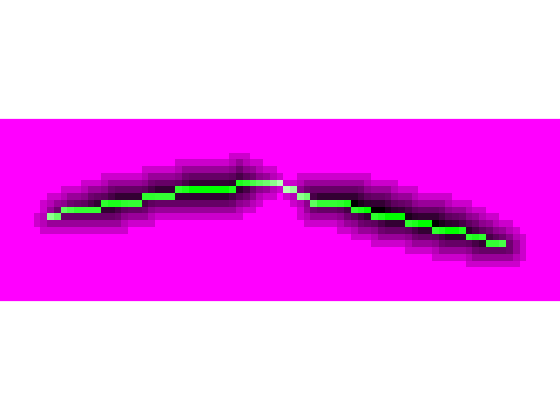

% subcell 细胞的bw图像 mask
minCellThickness = sqrt(2);

minCellLength = 20;%20-30

subcell = logical(subcell);
D = -bwdist(~subcell);
bw_thin = bwmorph(subcell, 'thin', inf);
bw_perm = bwperim(subcell);
figure,imshowpair(bw_thin,D);

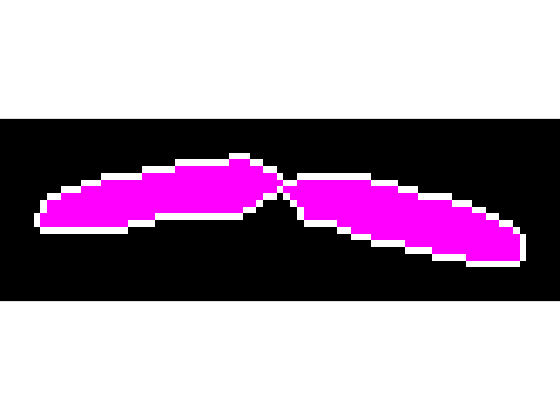

figure,imshowpair(bw_perm,subcell);

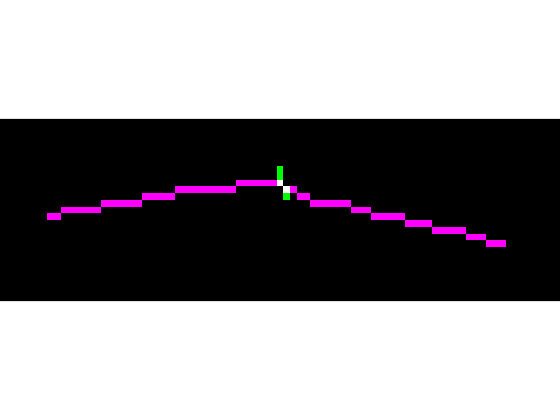

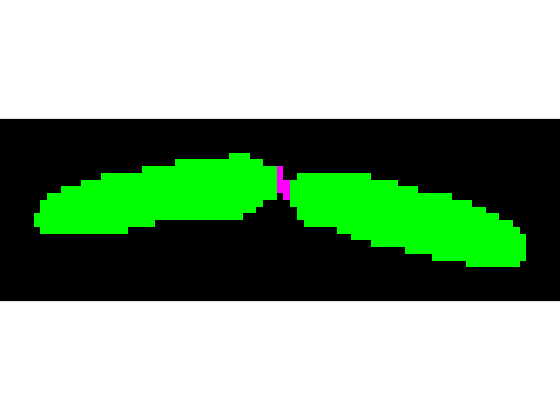


s_thin = regionprops(bw_thin,'PixelIdxList','PixelList');


cellThickness = D([s_thin.PixelIdxList]);
cellThickness = abs(cellThickness);

fposIdx = find((cellThickness <= minCellThickness));%找到<2pixel宽度的点 8连通 包括对角线
% 薄弱连接点

thinLength = sum(bw_thin(:));

cutcell = subcell;
% 将连接<2pixel的点 进行人为切断分割
segline  = false(size(subcell));

markPosIdx = 0;% 需要判断薄弱连接点之间的距离 不能小于minCellLength
for i = 1:numel(fposIdx)
    
    if min([fposIdx(i)-markPosIdx,thinLength-fposIdx(i)]) < minCellLength
        continue
    end
    markPosIdx = fposIdx(i);
    [row,col] = ind2sub(size(subcell),s_thin.PixelIdxList(fposIdx(i)));
    segline(row-2:row+2,col-2:col+2) = bw_thin(row-2:row+2,col-2:col+2)';%5*5box转置进行切割
    figure,imshowpair(segline,bw_thin)
    %     segline = imdilate(segline,ones(2));
    segline = bwmorph(segline,'diag');%Uses diagonal fill to eliminate 8-connectivity 
    cutcell = and(cutcell,~segline);
    figure,imshowpair(cutcell,segline);
end

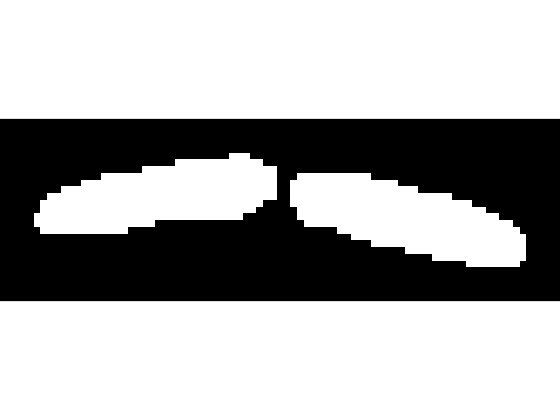


figure,imshow(cutcell)

s_temp = regionprops(cutcell,'all');

% for i = 1:numel(fposIdx)
%
%     if min([fposIdx(i)-markPosIdx,thinLength-fposIdx(i)]) > minCellLength
%         markPosIdx = fposIdx(i);
%         [row,col] = ind2sub(size(subcell),s_thin.PixelIdxList(fposIdx(i)));
%         segline(row-2:row+2,col-2:col+2) = bw_thin(row-2:row+2,col-2:col+2)';%5*5box转置进行切割
%         figure,imshowpair(segline,bw_thin)
%         cutcell = and(cutcell,~segline);
% %         for irow = row-1:row+1
% %             for icol = col-1:col+1
% %                 ind = sub2ind(size(subcell),irow,icol);
% %                 if abs(D(ind)) <= minCellThickness
% %                     cutcell(ind) = false;
% %                 end
% %             end
% %
% %         end
%     end
%
% end
% figure,imshow(cutcell)